%This file was used to construct most of the thesis plots 
%It gives examples of every step of the way used in the main generation
%file with example plots to visualize different steps

seizures = fullfile(pwd, 'bou/S/');
normal = fullfile(pwd, 'bou/Z/');
interictal = fullfile(pwd, 'bou/F/');

fs = 173.61;
file_list_seizure = dir(fullfile(seizures, '*.txt'));
file_list_normal = dir(fullfile(normal, '*.txt'));
file_list_interictal = dir(fullfile(interictal, '*.txt'));

beta_val = [0, 0.125, 0.25, 0.375, 0.5, 0.625, 0.75, 0.875, 1, 1.125, 1.25, 1.375, 1.5, 1.625, 1.75, 1.875, 2, 2.125, 2.25, 2.375, 2.5, 2.625, 2.75, 2.875, 3, 3.125, 3.25, 3.375, 3.5, 3.625, 3.75, 3.875, 4];


seizure = [];
for i = 1 : length(file_list_seizure)
    seizure = [seizure, load(fullfile(seizures, file_list_seizure(i).name))];
end
deviation = std(seizure(:));


%Give example of added noises
noise_levels = [0,0.05,0.1,0.2,0.3];
newSignals = zeros(length(noise_levels), size(seizure,1),size(seizure,2));

for i = 1 : length(noise_levels)
    noiseDeviation = deviation*noise_levels(i);
    noise = noiseDeviation*randn(size(seizure));
    newSignals(i,:,:) = seizure+noise;
end
t = 5; % Window size in seconds
start = 1;
finish = round(t * fs);

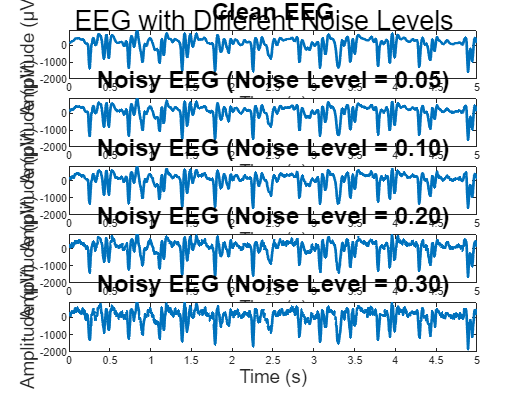

% Plot original and noisy signals (first 1000 samples for clarity)
t = (1:finish) / fs; % Time in seconds
figure;

for i = 1:length(noise_levels)
    subplot(length(noise_levels), 1, i);
    plot(t, squeeze(newSignals(i, 1:finish, 1)), 'LineWidth', 2); % Thicker line
    if i == 1
        title('Clean EEG', 'FontSize', 18); % Fixed: Corrected title for clean signal
    else
        title(sprintf('Noisy EEG (Noise Level = %.2f)', noise_levels(i)), 'FontSize', 18); % Larger font
    end
    xlabel('Time (s)', 'FontSize', 14); % Larger font
    ylabel('Amplitude (µV)', 'FontSize', 14); % Larger font
end
sgtitle('EEG with Different Noise Levels', 'FontSize', 20); % Larger font for overall title
hold off;

signals = zeros(length(noise_levels),finish,1);
for i = 1: length(noise_levels)
    signals(i,:,:) =  newSignals(i,1:finish,1);
end

%Compute some example recurrence plots
alphas = zeros(size(signals));
betas = zeros(size(signals));
deltas = zeros(size(signals));
thetas = zeros(size(signals));

taus = zeros(length(noise_levels),4);
embeddings = zeros(length(noise_levels),4);
RM_alpha = cell(1,length(noise_levels));
RM_beta = cell(1,length(noise_levels));
RM_delta = cell(1,length(noise_levels));
RM_theta = cell(1,length(noise_levels));

for i = 1 : size(signals,1)
    [alpha, beta, delta, theta] = normalize_data(signals(i,:,:)', fs, 1);

    alphas(i,:,:) = alpha;
    betas(i,:,:) = beta;
    deltas(i,:,:) = delta;
    thetas(i,:,:) = theta;
    signal = [alpha, beta, delta, theta];
    taus(i,:) = computeTau(signal);
    embeddings(i,:) = computeEmbeddings(signal,taus(i,:));

    RM_alpha{i} = computeForBand(alpha, embeddings(i,1), taus(i,1), 2);
    RM_beta{i}  = computeForBand(beta, embeddings(i,2), taus(i,2), 2);
    RM_delta{i} = computeForBand(delta, embeddings(i,3), taus(i,3), 2);
    RM_theta{i} = computeForBand(theta, embeddings(i,4), taus(i,4), 2);

end

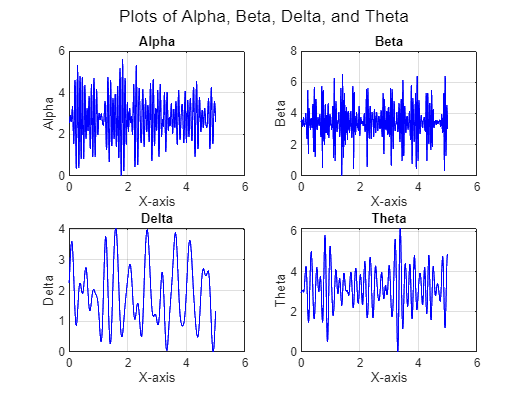

% Create a new figure
figure;
finish = 868;
x = (1:finish) / fs;
% Subplot for alpha
subplot(2, 2, 1); % 2x2 grid, position 1
plot(x, alphas(1,:,:), 'b-', 'LineWidth', 0.75); % Blue solid line
xlabel('X-axis'); % Replace with appropriate label, e.g., 'Time'
ylabel('Alpha'); % Y-axis label
title('Alpha'); % Title
grid on; % Add grid

% Subplot for beta
subplot(2, 2, 2); % 2x2 grid, position 2
plot(x, betas(1,:,:), 'b-', 'LineWidth', 0.75); % Blue solid line
xlabel('X-axis'); % Replace with appropriate label
ylabel('Beta'); % Y-axis label
title('Beta'); % Title
grid on;

% Subplot for delta
subplot(2, 2, 3); % 2x2 grid, position 3
plot(x, deltas(1,:,:), 'b-', 'LineWidth', 0.75); % Blue solid line
xlabel('X-axis'); % Replace with appropriate label
ylabel('Delta'); % Y-axis label
title('Delta'); % Title
grid on;

% Subplot for theta
subplot(2, 2, 4); % 2x2 grid, position 4
plot(x, thetas(1,:,:), 'b-', 'LineWidth', 0.75); % Blue solid line
xlabel('X-axis'); % Replace with appropriate label
ylabel('Theta'); % Y-axis label
title('Theta'); % Title
grid on;


% Optional: Adjust figure layout for better spacing
sgtitle('Plots of Alpha, Beta, Delta, and Theta'); % Overall figure title

function RM_thresh = computeForBand(signal,embedding,tau,beta_div)
    RM_thresh = computeRM_blockedkronecker_nonsymmetric(signal, embedding, tau, 10, beta_div);
end

% Function: Normalize data with parallel channel filtering copied from
% other file
function [alpha, beta, delta, theta] = normalize_data(all_data, fs, normalize)
    % NORMALIZE_DATA applies Hampel filtering, FIR-based bandpass filtering to EEG data,
    % and performs Z-score normalization shifted to positive values for each channel.
    %
    % Input:
    %   all_data - [samples x channels] matrix
    %   fs - Sampling frequency in Hz
    % Output:
    %   alpha, beta, delta, theta - filtered and normalized data matrices

    [n_samples, n_channels] = size(all_data);
    order = 200; % FIR filter order

    % === Step 1: Hampel filter for outlier removal ===
    all_data = hampel(all_data); % Ensure hampel is thread-safe

    % === Step 2: FIR filter design (computed once, shared across workers) ===
    bands_delta = fir1(order, [0.5 4] / (fs/2));
    bands_theta = fir1(order, [4 8] / (fs/2));
    bands_alpha = fir1(order, [8 13] / (fs/2));
    bands_beta = fir1(order, [13 30] / (fs/2));

    % === Step 3: Preallocate filtered data ===
    delta = zeros(n_samples, n_channels);
    theta = zeros(n_samples, n_channels);
    alpha = zeros(n_samples, n_channels);
    beta = zeros(n_samples, n_channels);
    
    
    % === Step 4: Apply FIR filters per channel in parallel ===
    for ch = 1:n_channels
        delta(:,ch) = conv(all_data(:,ch), bands_delta, 'same');
        theta(:,ch) = conv(all_data(:,ch), bands_theta, 'same');
        alpha(:,ch) = conv(all_data(:,ch), bands_alpha, 'same');
        beta(:,ch) = conv(all_data(:,ch), bands_beta, 'same');
    end
    if(normalize==0)
        return
    end
    % === Step 5: Z-Score Normalization + Shift to Positive ===
    delta = z_score_shifted(delta);
    theta = z_score_shifted(theta);
    alpha = z_score_shifted(alpha);
    beta = z_score_shifted(beta);
end

% Helper: Z-score normalize and shift to make all values positive
function z = z_score_shifted(x)
    z = (x - mean(x)) / std(x); % Z-score normalization
    z = z - min(z) + 0.0000001;   % Shift so minimum is 0
end

% Function: Compute time delay (tau)
function taus = computeTau(signals)
    for i = 1: size(signals,2)
        x_mutual = mutual(signals(:,i), 32, 20); 
        [~, min_idx] = findpeaks(-x_mutual);
        if isempty(min_idx)
            taus(i) = length(x_mutual); % Default to max if no clear minimum
        else
            taus(i) = min_idx(1); % First minimum
        end
    end 
end
% Function: Compute embedding dimension
function embeddings = computeEmbeddings(signals, taus) % Fixed typo
    embeddings = [20,20,20,20]; % Default

    for i = 1:length(taus)
        fnn = false_nearest(signals(:,i), 1, 20, taus(i), 10); % Ensure false_nearest is thread-safe
        
        for j = 1:20
            if (fnn(j, 2) <= 0.01 && ~isnan(fnn(j, 2)))
                embeddings(i) = j;
                break;
            end
        end
    end
    
end

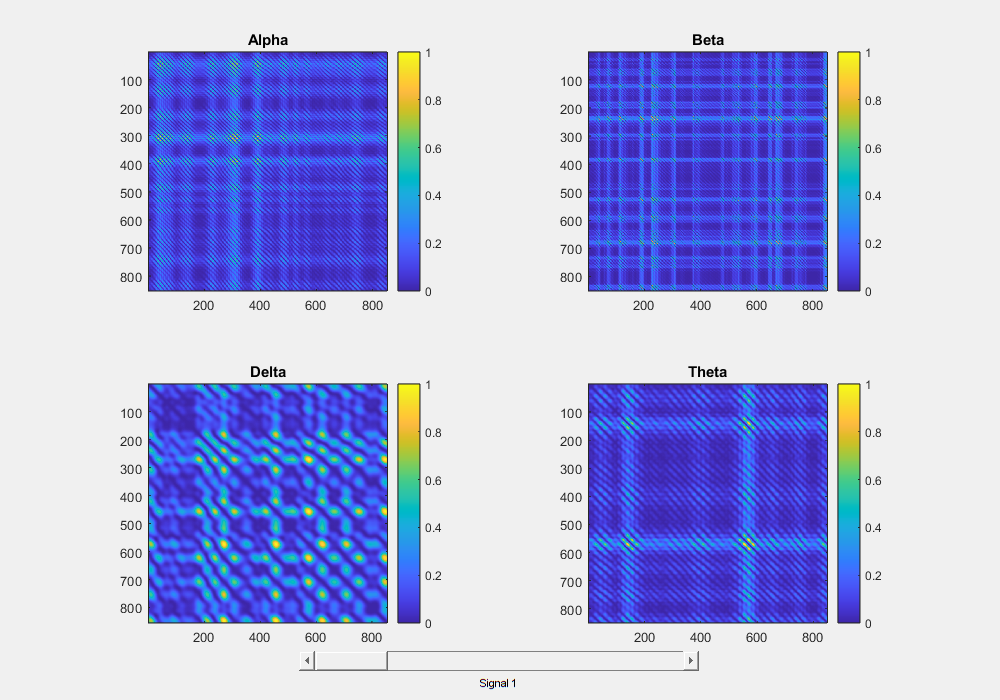

% Assumes RM_alpha, RM_beta, RM_delta, RM_theta are cell arrays
% Each cell contains a 2D recurrence plot (double array)
RecurrencePlotViewer(RM_alpha, RM_beta, RM_delta, RM_theta);

function RecurrencePlotViewer(RM_alpha, RM_beta, RM_delta, RM_theta)

    numSignals = length(RM_alpha);  % Number of signals

    % Create figure
    f = figure('Name', 'Recurrence Plots Viewer', ...
               'NumberTitle', 'off', ...
               'Position', [100, 100, 1000, 700]);

    % Create axes for 4 subplots
    ax1 = subplot(2, 2, 1);
    ax2 = subplot(2, 2, 2);
    ax3 = subplot(2, 2, 3);
    ax4 = subplot(2, 2, 4);

    % Create slider
    sld = uicontrol('Style', 'slider', ...
        'Min', 1, 'Max', numSignals, 'Value', 1, ...
        'SliderStep', [1/(numSignals-1), 1/(numSignals-1)], ...
        'Position', [300, 30, 400, 20], ...
        'Callback', @updatePlots);

    % Create label
    txt = uicontrol('Style', 'text', ...
        'Position', [450, 5, 100, 20], ...
        'String', 'Signal 1');

    % Initial plot
    updatePlots();

    % Callback function for slider
    function updatePlots(~, ~)
        idx = round(get(sld, 'Value'));
        set(txt, 'String', ['Signal ' num2str(idx)]);

        % Update each plot
        axes(ax1);
        imagesc(RM_alpha{idx});
        axis square;
        title('Alpha');
        colorbar;

        axes(ax2);
        imagesc(RM_beta{idx});
        axis square;
        title('Beta');
        colorbar;

        axes(ax3);
        imagesc(RM_delta{idx});
        axis square;
        title('Delta');
        colorbar;

        axes(ax4);
        imagesc(RM_theta{idx});
        axis square;
        title('Theta');
        colorbar;
    end

end

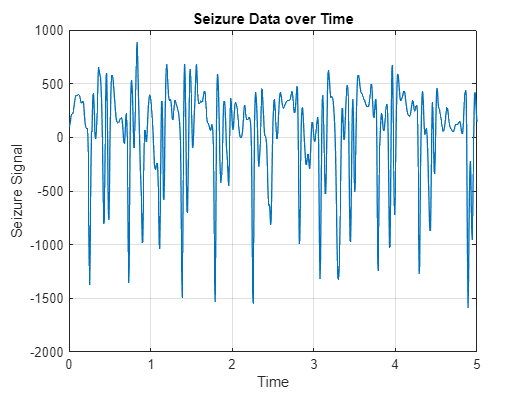

finish = 868;
t = (1:finish) / fs;
figure;
plot(t, seizure(1:finish,1));
xlabel('Time');
ylabel('Seizure Signal');
title('Seizure Data over Time');
grid on;

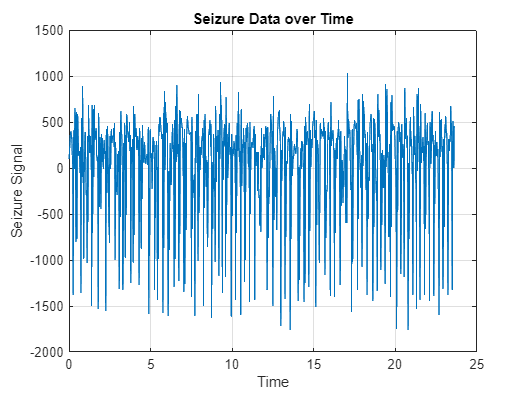

finish = 4097;
t = (1:finish) / fs;
figure;
plot(t, seizure(:,1));
xlabel('Time');
ylabel('Seizure Signal');
title('Seizure Data over Time');
grid on;

[alpha, beta, delta, theta] = normalize_data(signals(1,:,:)', fs, 0);

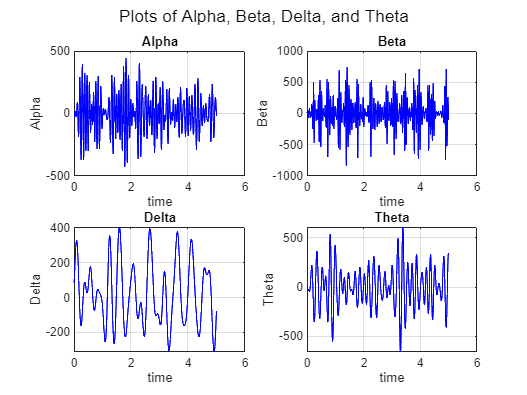

% Create a new figure
figure;
finish = 868;
x = (1:finish) / fs;
% Subplot for alpha
subplot(2, 2, 1); % 2x2 grid, position 1
plot(x, alpha, 'b-', 'LineWidth', 0.75); % Blue solid line
xlabel('time'); % Replace with appropriate label, e.g., 'Time'
ylabel('Alpha'); % Y-axis label
title('Alpha'); % Title
grid on; % Add grid

% Subplot for beta
subplot(2, 2, 2); % 2x2 grid, position 2
plot(x, beta, 'b-', 'LineWidth', 0.75); % Blue solid line
xlabel('time'); % Replace with appropriate label
ylabel('Beta'); % Y-axis label
title('Beta'); % Title
grid on;

% Subplot for delta
subplot(2, 2, 3); % 2x2 grid, position 3
plot(x, delta, 'b-', 'LineWidth', 0.75); % Blue solid line
xlabel('time'); % Replace with appropriate label
ylabel('Delta'); % Y-axis label
title('Delta'); % Title
grid on;

% Subplot for theta
subplot(2, 2, 4); % 2x2 grid, position 4
plot(x, theta, 'b-', 'LineWidth', 0.75); % Blue solid line
xlabel('time'); % Replace with appropriate label
ylabel('Theta'); % Y-axis label
title('Theta'); % Title
grid on;

% Optional: Adjust figure layout for better spacing
sgtitle('Plots of Alpha, Beta, Delta, and Theta'); % Overall figure title

%Compute AMI
signal_1 = [
    squeeze(alphas(1,:,:));
    squeeze(betas(1,:,:));
    squeeze(deltas(1,:,:));
    squeeze(thetas(1,:,:))
];

x_mutual = mutual(squeeze(betas(1,:,:)), 32, 20); 

[~, min_idx] = findpeaks(-x_mutual);
if isempty(min_idx)
    ta = length(x_mutual); % Default to max if no clear minimum
else
    ta = min_idx(1); % First minimum
end

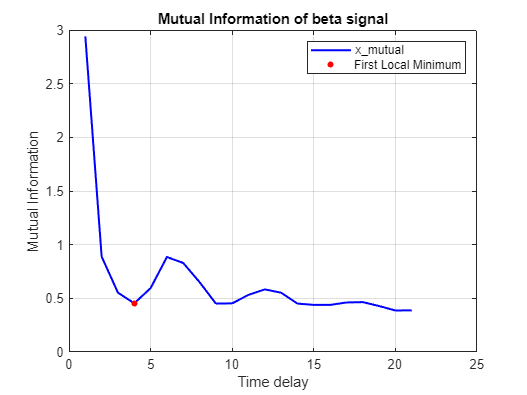

% Plot x_mutual
figure;
plot(x_mutual, 'b', 'LineWidth', 1.5);
hold on;

% Highlight the minimum point at ta
plot(ta, x_mutual(ta), 'ro', 'MarkerSize', 4, 'MarkerFaceColor', 'r');

% Annotations and labels
xlabel('Time delay');
ylabel('Mutual Information');
title('Mutual Information of beta signal');
legend('x\_mutual', 'First Local Minimum');
grid on;

fnn = false_nearest(betas(1,:,:), 1, 20, ta, 10); % Ensure false_nearest is thread-safe
        
for j = 1:20
    if (fnn(j, 2) <= 0.01 && ~isnan(fnn(j, 2)))
        emb = j;
        break;
    end
end

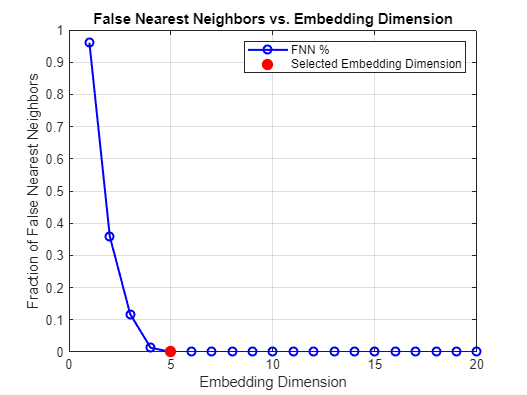

% Plot FNN percentages
figure;
plot(1:20, fnn(:,2), 'b-o', 'LineWidth', 1.5);
hold on;

% Highlight the chosen embedding dimension
plot(emb, fnn(emb,2), 'ro', 'MarkerSize', 8, 'MarkerFaceColor', 'r');

% Annotations
xlabel('Embedding Dimension');
ylabel('Fraction of False Nearest Neighbors');
title('False Nearest Neighbors vs. Embedding Dimension');
legend('FNN %', 'Selected Embedding Dimension');
grid on;

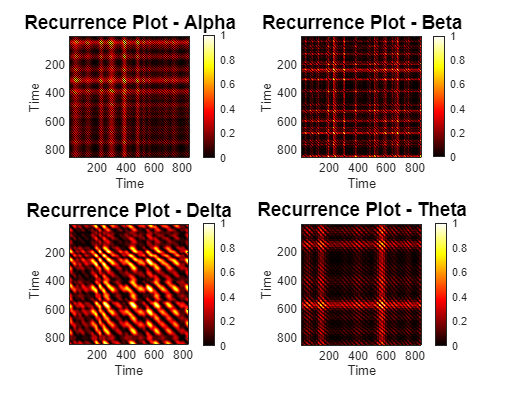

figure;

% Alpha band recurrence plot
subplot(2,2,1);
imagesc(RM_alpha{5});
colormap("hot");
axis square;
title('Recurrence Plot - Alpha', 'FontSize', 14);
xlabel('Time');
ylabel('Time');
colorbar;

% Beta band recurrence plot
subplot(2,2,2);
imagesc(RM_beta{5});
colormap("hot");
axis square;
title('Recurrence Plot - Beta', 'FontSize', 14);
xlabel('Time');
ylabel('Time');
colorbar;

% Delta band recurrence plot
subplot(2,2,3);
imagesc(RM_delta{5});
colormap("hot");
axis square;
title('Recurrence Plot - Delta', 'FontSize', 14);
xlabel('Time');
ylabel('Time');
colorbar;

% Theta band recurrence plot
subplot(2,2,4);
imagesc(RM_theta{5});
colormap("hot");
axis square;
title('Recurrence Plot - Theta', 'FontSize', 14);
xlabel('Time');
ylabel('Time');
colorbar;

beta_values = [0,1,2,3.5];
for i = 1 : 4
    RM_delta_2{i}  = computeForBand(delta, embeddings(1,3), taus(1,3), beta_values(i));
end


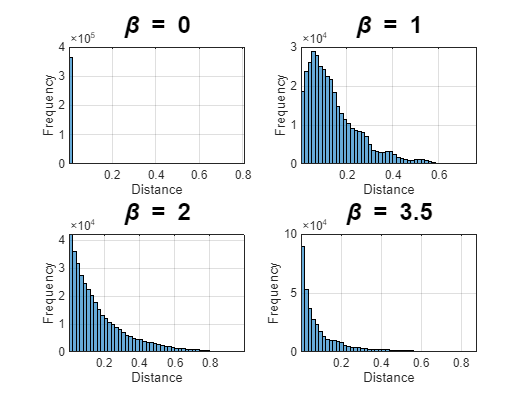

figure;
beta_values = [0,1,2,3.5];
for i = 1:4
    % Extract raw distance matrix
    D = RM_delta_2{i};  % Make sure this is the raw distance matrix, not binary

    % Extract unique pairwise distances (upper triangle, no diagonal)
    dists = D(triu(true(size(D)), 1));
    
    % Plot histogram
    subplot(2, 2, i);
    histogram(dists, 50);  % 50 bins by default
    
    % Set dynamic x-axis limits based on the data
    xlim([min(dists), max(dists)]);
    
    % Add labels and formatting
    title(['\beta = ', num2str(beta_values(i))], 'FontSize', 18);
    xlabel('Distance'); 
    ylabel('Frequency');
    grid on;

end

for i = 1 : length(RM_delta_2)
    RM = RM_delta_2{i};
    RM_flat = RM(:);
    p_min = prctile(RM_flat,5);
    p_max = prctile(RM_flat,90);
    RM_norm{i} = (RM-p_min)/(p_max-p_min);
    RM_norm{i} = max(0,min(1,RM_norm{i}));
end

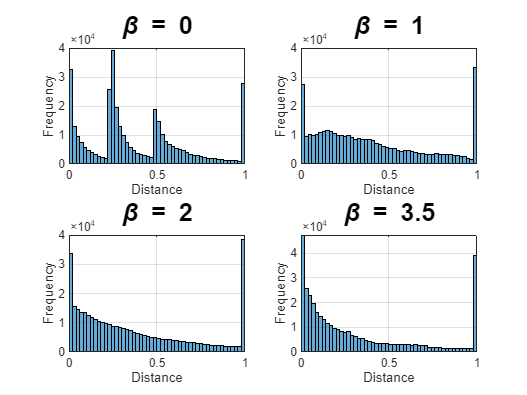

figure;
for i = 1:4
    % Extract raw distance matrix
    D = RM_norm{i};  % Make sure this is the raw distance matrix, not binary

    % Extract unique pairwise distances (upper triangle, no diagonal)
    dists = D(triu(true(size(D)), 1));
    
    % Plot histogram
    subplot(2, 2, i);
    histogram(dists, 50);  % 50 bins by default
    
    % Set dynamic x-axis limits based on the data
    xlim([min(dists), max(dists)]);
    
    % Add labels and formatting
    title(['\beta = ', num2str(beta_values(i))], 'FontSize', 19);
    xlabel('Distance'); 
    ylabel('Frequency');
    grid on;

end

range = [0.125, 0.25, 0.375, 0.5, 0.625, 0.75, 0.875, 1, 1.125, 1.25, 1.375, 1.5, 1.625, 1.75, 1.875, 2];
for i = 1 : length(range)
    for j = 1 : length(beta_values)
        RM_flat = RM(:);
        p_min = prctile(RM_flat,5);
        p_max = prctile(RM_flat,90);
        RM_norm2 = (RM-p_min)/(p_max-p_min);
        RM_norm2 = max(0,min(1,RM_norm2));
        RM_flat = RM_norm2(:);
        std_flat(i,j) = range(i)*mad(RM_flat);
    end 
end

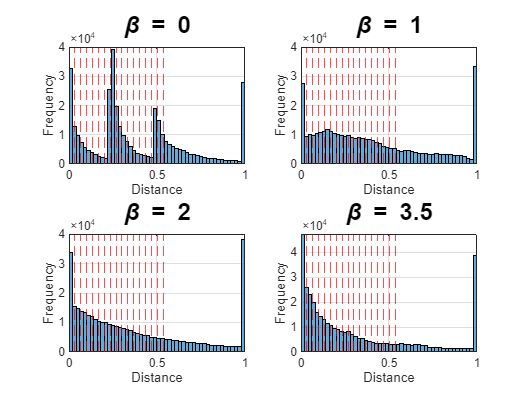

figure;
for i = 1:length(beta_values)
    % Extract raw distance matrix
    D = RM_norm{i}; % Raw distance matrix, not binary
    
    % Extract unique pairwise distances (upper triangle, no diagonal)
    dists = D(triu(true(size(D)), 1));
    
    % Plot histogram
    subplot(2, 2, i);
    histogram(dists, 50); % 50 bins
    hold on;
    
    % Set dynamic x-axis limits based on the data
    xlim([min(dists), max(dists)]);
    
    % Mark thresholds from std_flat for this beta
    thresholds = std_flat(:,i); % Thresholds for beta_values(i)
    for k = 1:length(thresholds)
        xline(thresholds(k), '--','Color', 'r', 'LineWidth', 0.5, 'LabelVerticalAlignment', 'bottom');
    end
    
    % Add labels and formatting
    title(['\beta = ', num2str(beta_values(i))], 'FontSize', 18);
    xlabel('Distance');
    ylabel('Frequency');
    grid on;
    
    hold off;
end

range2 = [0.5,1,1.5,2];
for i = 1:length(range2)
    RM = RM_norm{4};
    RM_flat = RM(:);
    RM_Thresh{i} = RM<(range2(i)*mad(RM_flat));
end

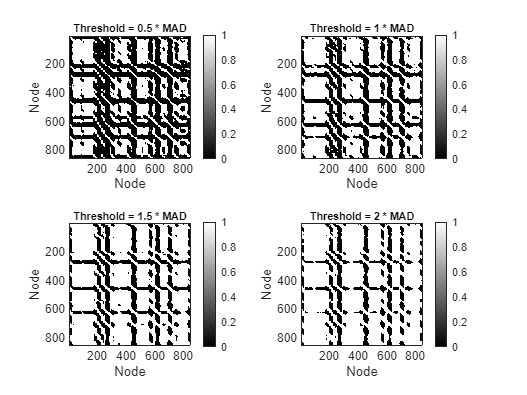

% Plot the binary distance matrices
figure;
for i = 1:length(range2)
    % Create subplot (2 rows, 3 columns)
    subplot(2, 2, i);
    
    % Plot binary matrix as a heatmap
    imagesc(RM_Thresh{i});
    
    % Set colormap to grayscale (1 = white, 0 = black)
    colormap(gray);
    
    % Add labels and formatting
    title(['Threshold = ', num2str(range2(i)), ' * MAD'], 'FontSize', 8);
    xlabel('Node'); 
    ylabel('Node');
    axis square;  % Make the plot square for better visualization
    colorbar;  % Optional: show colorbar to indicate 0/1 values
end

Error using findpeaks>parse_inputs (line 225)
Data set must contain at least 3 samples.

Error in findpeaks (line 135)
  = parse_inputs(isInMATLAB,Yin,varargin{:});

Error in creationProcess>compute